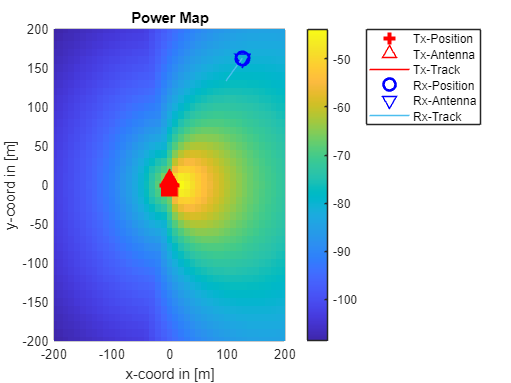

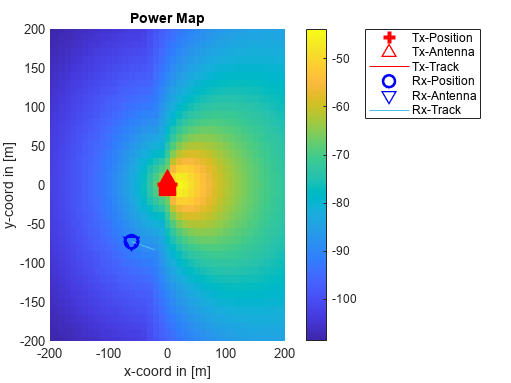

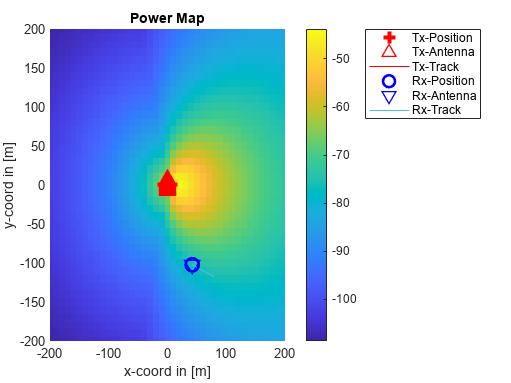

clear all; close all; clc;

% Определяем, нужно ли создавать набор данных
dataset_creation_flag = 0;

% Установка количества образцов данных в зависимости от режима отладки
if dataset_creation_flag == 1
    num_samples = 2500;
else
    num_samples = 3;
end

% Параметры трека мобильного терминала
track_length = 100; % [м]
track_speed = 0.9; % [м/с]
feedback_interval = 5; % [с]

% Параметры сценария моделирования
area_length = 400; % [м^2]
timeslots = 10;
feedback_times = (0:timeslots-1) * feedback_interval;
feedback_locs = feedback_times * track_speed;
feedback_profile = [feedback_times; feedback_locs];

% Параметры для MIMO
num_rx_antennas = 1; % количество антенн на приемнике (мобильном терминале)
num_tx_antennas = 32; % количество антенн на передатчике (базовой станции)
num_subcarriers = 128; % количество поднесущих
subcarrier_bandwidth = 2e4; % Ширина полосы пропускания поднесущих в Гц

% Создание набора данных
H_dataset = zeros(num_samples, timeslots, num_tx_antennas, num_subcarriers);

for i_sample = 1:num_samples
    
    % Инициализация сценария моделирования
    simulation_params = qd_simulation_parameters;
    simulation_params.center_frequency = 3.0e8; % несущая частота в Гц (300 МГц)
    simulation_params.show_progress_bars = 0; % Отключение визуализации выполнения
    num_users = 1;
    
    % Создание трека для мобильного терминала

    % Выбор типа трека (линейный или кривой)
%     track_type = randi([1, 2]); % случайный выбор между 1 и 2
    track_type = 1;

    if track_type == 1
        % Линейный трек
        x_init = area_length * rand(1) - area_length/2; % случайная инициализация координаты x
        y_init = area_length * rand(1) - area_length/2; % случайная инициализация координаты y
        theta = pi * (2 * rand(1) - 1); % случайный угол направления
        track = qd_track('linear', track_length, theta); % создание линейного трека
    else
        % Кривой трек
        radius = 50 + rand() * 150; % случайный радиус
        x_init = area_length * rand(1) - area_length/2; % случайная координата x центра круга
        y_init = area_length * rand(1) - area_length/2; % случайная координата y центра круга
        arc_angle = pi * (rand(1) - 0.5); % случайный угол дуги
        track = qd_track('circular', radius, x_init, y_init, arc_angle); % создание кривого трека
    end

    track.initial_position = [x_init; y_init; 1.5]; % начальная позиция
    track.set_speed(track_speed);
    track.interpolate('time', feedback_interval, feedback_profile);
    track.segment_index = 1;
    track.scenario = {'3GPP_3D_UMa_NLOS'}; % выбор сценария {'BERLIN_UMa_LOS', '3GPP_3D_UMa_LOS', 'BERLIN_UMa_NLOS','3GPP_3D_UMa_NLOS'}
    track.name = 'Rx1'; % имя трека
    
    layout = qd_layout(simulation_params); % Создание объекта сценария моделирования
    
    layout.rx_track = track; % Назначение трека для мобильного терминала
    layout.tx_position = [0, 0, 20]'; % Положение базовой станции
    
    % Настройка антенн
    layout.rx_array = qd_arrayant('omni'); % Мобильный терминал использует всенаправленную антенну
    % БС использует антенну из 32 элементов с поляризацией +/- 45 градусов. Наклон 8 градусов. 
    layout.tx_array = qd_arrayant.generate('3gpp-3d', num_rx_antennas, num_tx_antennas, simulation_params.center_frequency(1), 1);
    
    % Генерация коэффициентов каналов
    channels = layout.get_channels;
    
    % Оценка частотной характеристики каналов
    H_freq_response = zeros(timeslots, num_tx_antennas, num_subcarriers);
    for t_i = 1:timeslots
        H_freq_response(t_i, :, :) = channels.fr(num_subcarriers * subcarrier_bandwidth, num_subcarriers, t_i, 1);
    end
    
    H_dataset(i_sample, :, :, :) = H_freq_response(:, :, :);

    if dataset_creation_flag == 0
        % Вывод графика карты мощности
        figure; clf; hold on;
        [map, x_coords, y_coords] = layout.power_map(track.scenario, 'quick');
        % Визуализация карты мощности
        power = sum(map{1}, 4);
        imagesc(x_coords, y_coords, 10*log10(power));
        colorbar;
        xlabel('X (m)');
        ylabel('Y (m)');
        title('Power Map');
        layout.visualize([],[],0,0);
        axis([-200 200 -200 200])
        hold off;
    end
end

ans = 'Sample 1'

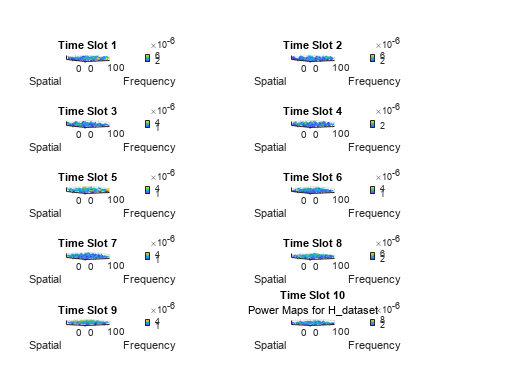

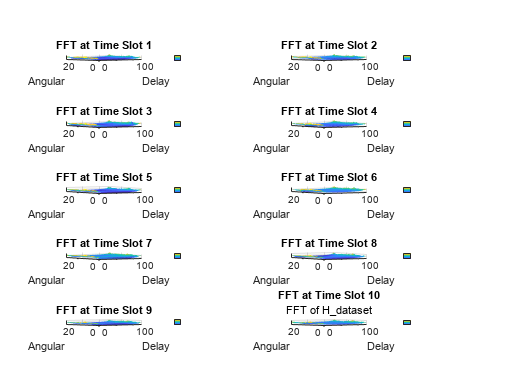

ans = 'Sample 2'

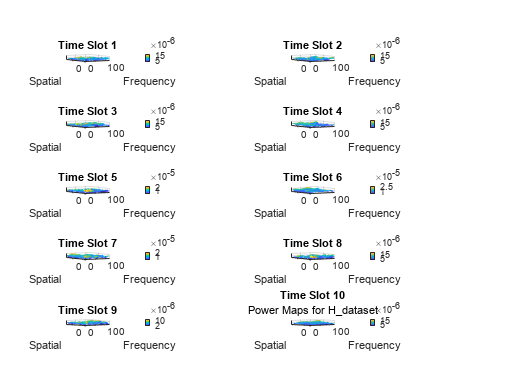

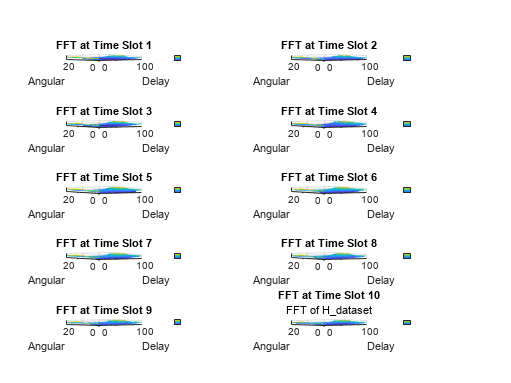

ans = 'Sample 3'

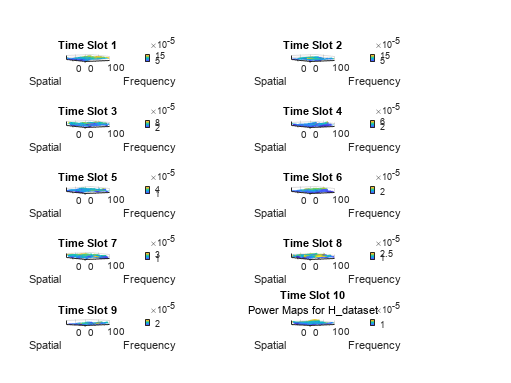

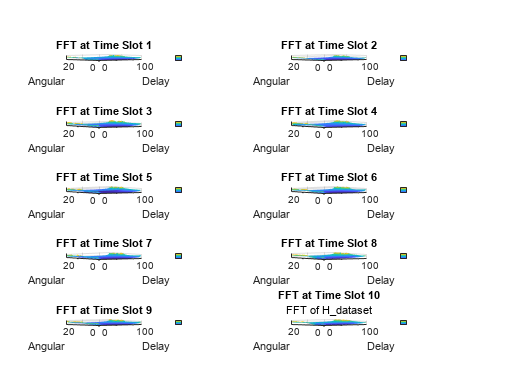


if dataset_creation_flag == 1
    % Сохранение набора данных
    filename = sprintf('H_quadriga_%d_%s.mat', num_samples, track.scenario);
    save(filename, 'H_dataset');
end


if dataset_creation_flag == 0
    % Вывод графиков для матриц H_dataset
    for i_sample = 1:num_samples
        sprintf('Sample %d', i_sample)
        H_dataset_sq = squeeze(H_dataset(i_sample, :, :, :));
        figure;
        for t_i = 1:timeslots
            subplot(timeslots/2, 2, t_i);
            surf(abs(squeeze(H_dataset_sq(t_i, :, :))), 'EdgeColor', 'none');
            colorbar;
            xlabel('Frequency');
            ylabel('Spatial');
            title(sprintf('Time Slot %d', t_i));
        end
%         subtitle('Power Maps for H\_dataset');
    
        % FFT график
        figure;
        for t_i = 1:timeslots
            subplot(timeslots/2, 2, t_i);
            fft2_H_dataset_sq = fft2(squeeze(H_dataset_sq(t_i, :, :)));
            surf(10*log10(abs(fft2_H_dataset_sq(:,:))), 'EdgeColor', 'none'); 
            colorbar;
            xlabel('Delay');
            ylabel('Angular');
            title(sprintf('FFT at Time Slot %d', t_i));
        end
%         subtitle('FFT of H\_dataset');
    end
end